# Localization and Beam Search Demo with Multiple TX and RX Arrays

Beam seach and angular localization are critical procedures in mmWave systems.  In this demo, you will learn to:

- Model nodes with multiple antenna arrays

- Create and visualize codebooks for the arrays

- Simulate beam search

- Extract path angles from synchronizaton and sounding measurements

## Creating Multiple Arrays

Since mmWave antenna elements are highly directive, each array typically has a limited steerable range.  For this reason, most mmWave UEs and gNBs have multiple arrays to provide 360 coverage.  For example, this figure is from the excellent paper from Qualcomm that shows possible UE designs with two or three arrays at 28 GHz.

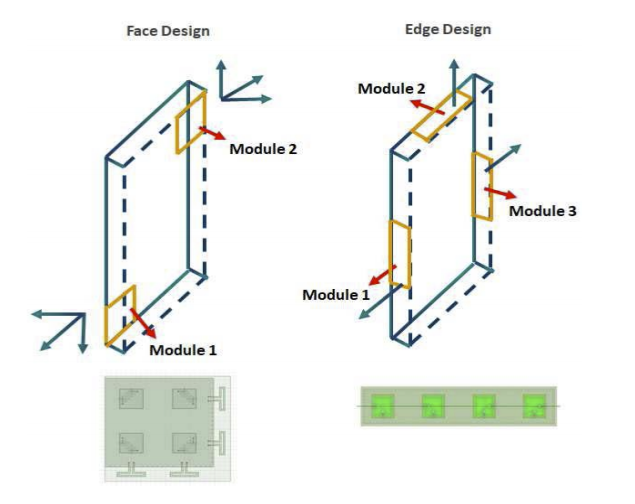

Figure from Raghavan, Vasanthan, et al. "Antenna placement and performance tradeoffs with hand blockage in millimeter wave systems." *IEEE Transactions on Communications* 67.4 (2019): 3082-3096.

In this demo, we will create simple multiple array layouts at the gNB and UE.  We first create the patch element that will be used in the simulation.  The patch is aligned so that its boresight is on the x-axis.

fc = 28e9;  % Carrier frequency

% Patch element design
elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0,1,0];


We next construct the arrays at the gNB and UE.  Consruct two URA with the given array dimensions.  Use a lambda / 2 separation.

% Number of antennas 
nantgNB = [4,4];
nantUE = 8;

% Construct the arrays
lambda = physconst('Lightspeed') / fc;
dsep = 0.5*lambda;
arrgNB = phased.URA(nantgNB,dsep,'ArrayNormal','x');
arrUE  = phased.ULA(nantUE,dsep);


Finally, we create a multiple arrays at the gNB and the UE.  The folder contains a `MultiArrayPlatform` class that contains a set of `ArrayPlatform`.  In this case, we will create three arrays at the UE and gNB.  The `alignAzimuth` method aligns them uniformly on the azimuth direction.  That is, at 0, 120 and -120 degrees -- all at zero elevation.  You can try more interesting layouts as well.

% Create the gNB multi-array platform
narrgNB = 3;
multiArrgNB = MultiArrayPlatform('narr', narrgNB, 'elem', elem, ...
    'array', arrgNB);
multiArrgNB.alignAzimuth(0);

% Create the UE multi-array platform
narrUE = 3;
multiArrUE = MultiArrayPlatform('narr', narrUE, 'elem', elem, ...
    'array', arrUE);
multiArrUE.alignAzimuth(0);


## Creating and Visualizing the Codebooks

In general, beam search occurs over a discrete set of direction defined by a *codebook*.  Formally, a codebook is simply a finite set of beamforming vectors on which a device transmits or receives signals.  Creating good codebooks in 3D requires some care.  But, to make the demo simple, we will just do a 2D codebook.  In this case, we can use the following command to create codebooks in the azimuth direction.  Running the function will create the following fields in the `MultiArrayPlatform `class:

- `codeWord:` An `nelem x ncw`  array where column `i` has the `i`-th column

- `cwArrInd`:  Codeword  `i` goes out over array `cwArrInd(i)`

- `azCw, elCw:  `The azimuth and elevation angle for each codeword

multiArrgNB.createCodebook('layout', 'azimuth');
multiArrUE.createCodebook('layout', 'azimuth');


To visualize the response of each codeword, we plot its array response in the azimuth direction.  There is one line for each codeword.  We see that each codeword is directed in one direction.

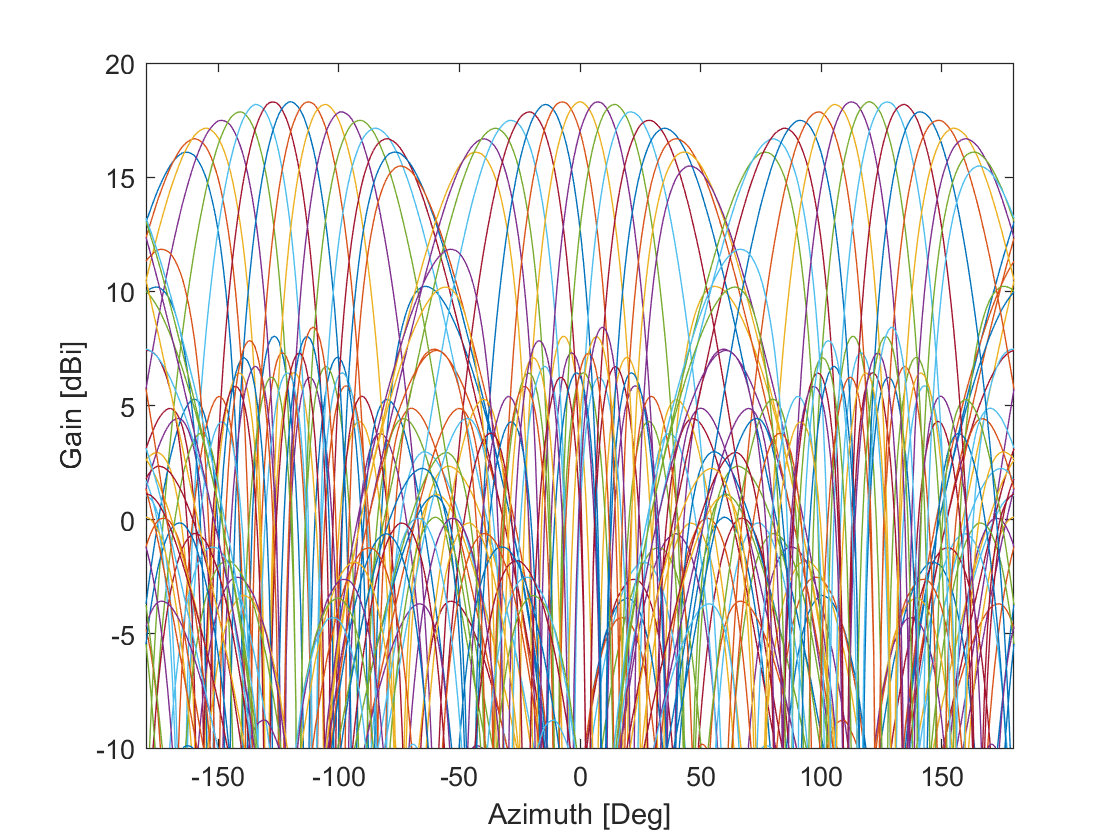

% Angles to test
nang = 360;
azTest = linspace(-180,180,nang)';
elTest = zeros(nang,1);

% Get complex gain in each codeword
gainComplex = multiArrgNB.cwGain(azTest,elTest);
gain = mag2db(abs(gainComplex));

% Plot the response for each codeword
plot(azTest, gain);
ylim([-10,20]);
xlim([-180,180]);
xlabel('Azimuth [Deg]');
ylabel('Gain [dBi]');

It is useful to plot the maximum gain along each direction.  We will plot the maximum response from each array as well as the best for all three arrays.  Each array has a peak coverage and the coverage is a little between the arrays.  This shortcoming arises from the finite steerable range of each array.

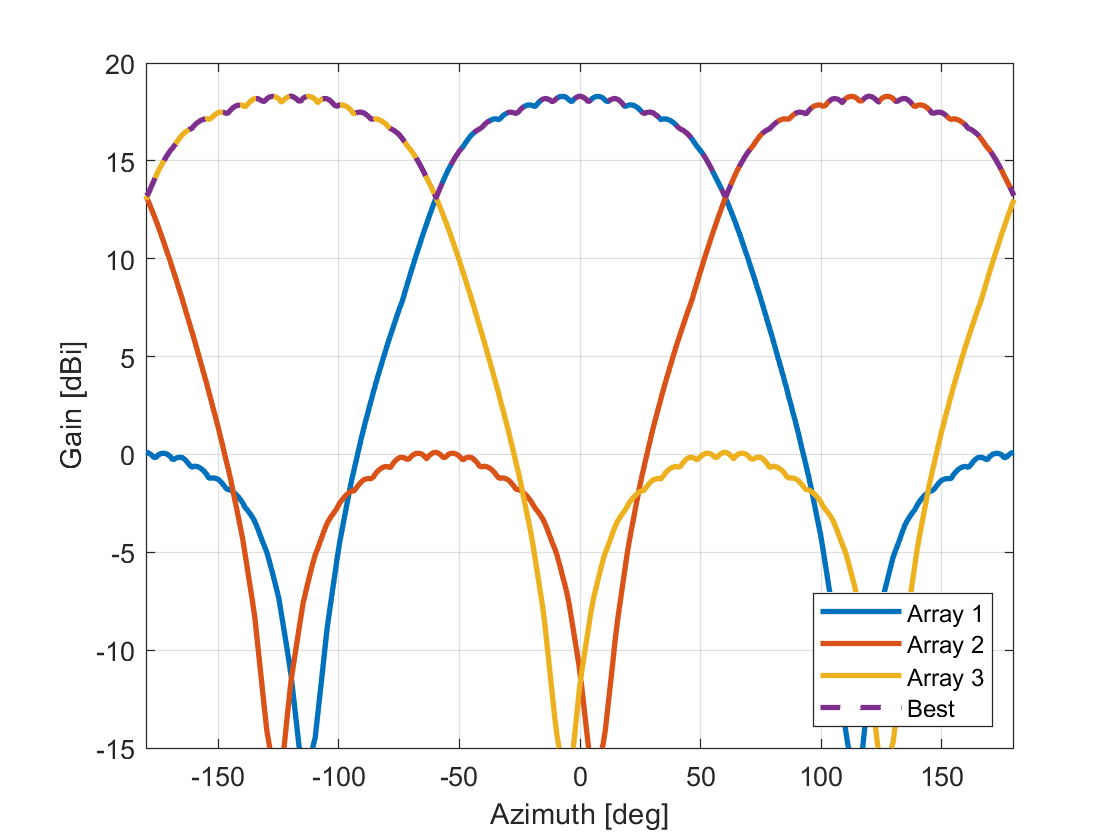

narr = multiArrgNB.getNumArrays();
gainMaxArr = zeros(nang, narr);
legStr = cell(narr+1,1);
for i = 1:narr
    % Get codewords corresponding to array i
    I = find(multiArrgNB.cwArrInd == i);
    
    % Find the maximum gain
    gainMaxArr(:,i) = max(gain(:,I), [], 2);
    
    % Create legend string
    legStr{i} = sprintf('Array %d', i);
end
legStr{narr+1} = 'Best';

% Plot the results
clf
plot(azTest, gainMaxArr, '-', 'Linewidth', 2);
hold on;
plot(azTest, max(gainMaxArr,[],2), '--', 'Linewidth', 2);
hold off;
xlim([-180,180]);
ylim([-15,20]);
legend(legStr, 'Location', 'southeast');
grid on;
xlabel('Azimuth [deg]');
ylabel('Gain [dBi]');

## Visualizing the Room Environment

We will now illustrate the beam search in an indoor where we have detailed ray tracing data.  See the `indoorDataDemo.mlx` file for the demo on this data.  The data for this experiment was created by Mingsheng Yin, a PhD student at NYU, with the Wireless Insite ray tracing tool from Remcomm.  We load the data as follows.

load Bowlus_Tx_3_pathData.mat

The data has one TX and many RX positions.  We will place the gNB at the TX and select one RX location.  Below are a few possible locations.  Select any one that you want.  

% Select an approximate RX position in the room
rxPos = [12,-6];   % A strong LOS point
% rxPos = [13,-12];  % A strong NLOS point
%rxPos = [15,-14];  % A weak NLOS point
%rxPos = [16,-15];  % A very weak NLOS point
% rxPos = [15.5, -10];

% Find the index in the ray tracing data closest to the desired position
d = sum((pathData.rxPos - rxPos).^2, 2);
[dmin, indRx] = min(d);

We now plot the TX and RX position

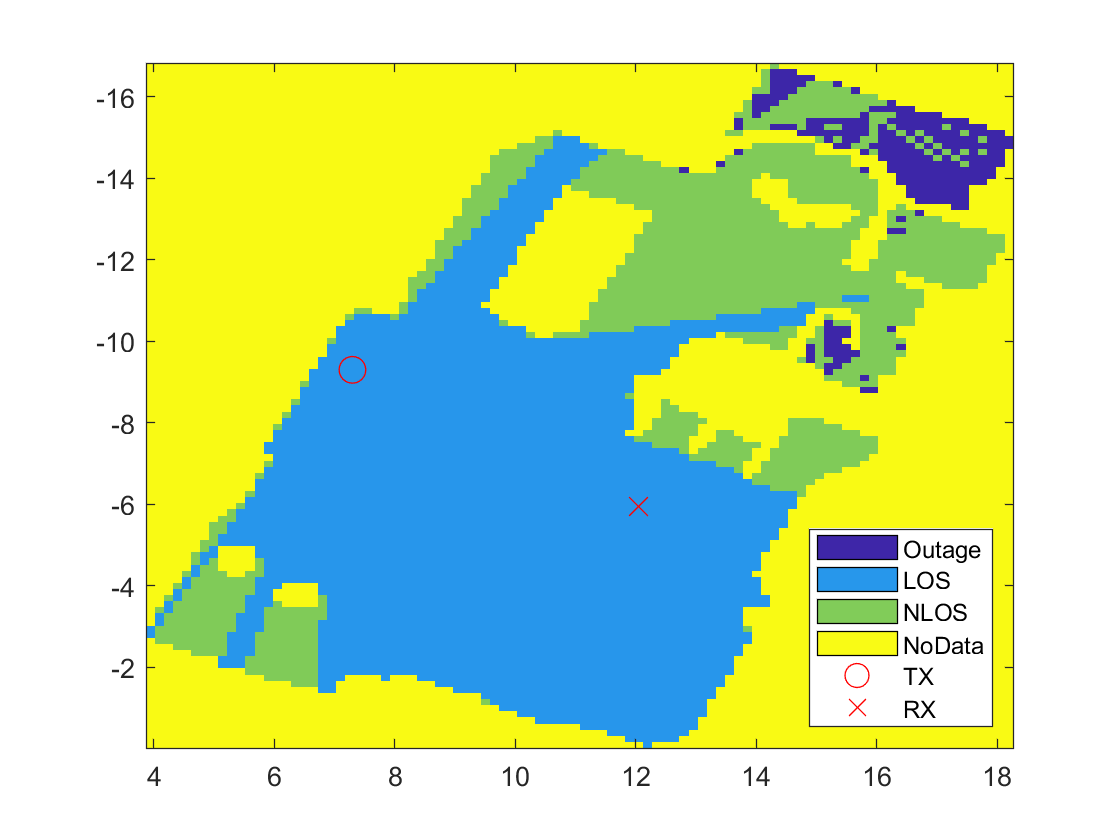

clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Create a mapper for plotting
mapper = DataMapper(pathData.rxPos, pathData.posStep);

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
plot(pathData.rxPos(indRx,1), pathData.rxPos(indRx,2), 'rx', ...
    'MarkerSize', 10, 'DisplayName', 'RX');
hold off;

% Display the legend
legend('Location', 'SouthEast');

## Simulating the Beam Search

In beam search, the TX sends a synchronization signal along each TX codeword, and the RX performs beamforming in each RX codeword direction.  In each TX-RX direction pair, the RX performs a match filter from which it can extract the channel response in that direction.  In total there will be `ncwRx x ncwTx` matched fiters where `ncwRx` and `ncwTx` are the number of TX and RX codewords.

To simulate the beam search, I have created a simple `DirSearchSim` class that can be created as follows.  

txPow = 23;  % TX power in dBm
dirSim = DirSearchSim('tx', multiArrgNB, 'rx', multiArrUE, 'txPow', txPow);

% Set the path parameters from the ray tracing data
dirSim.setPathParams(pathData,indRx);

We now simulate the beam search.  We could simulate the actual synchronization TX and RX in time-domain.  But, to make the simulation simple, we will assume we get a noisy version of the impulse response for each TX codeword.  This is obtained with the following command, which creates an array `h` of size  `NFFT x nantRx x narrRx x ncwTx` where 

`    h(t,i,j,k) =` channel response at time sample `t,` RX antenna `i`, RX array `j`, and TX codeword `k`   

% Get the RX channel response along each antenna and array
h = dirSim.chanResp();


We then compute the channel response along each RX codeword direction by performing a spatial beamforming on the channel response `h`.

hrx = dirSim.chanRespRxCw(h);


We can detect the beam directions by taking the maximum along the delays at each TX-RX pairs.  We divide the maximum by the average value to compute an SNR.  The SNR can be used for thresholding to see if there is a peak.  We plot the SNR in each directions along with the actual path locations.  We see that the peaks correspond loosely to actual path locations.

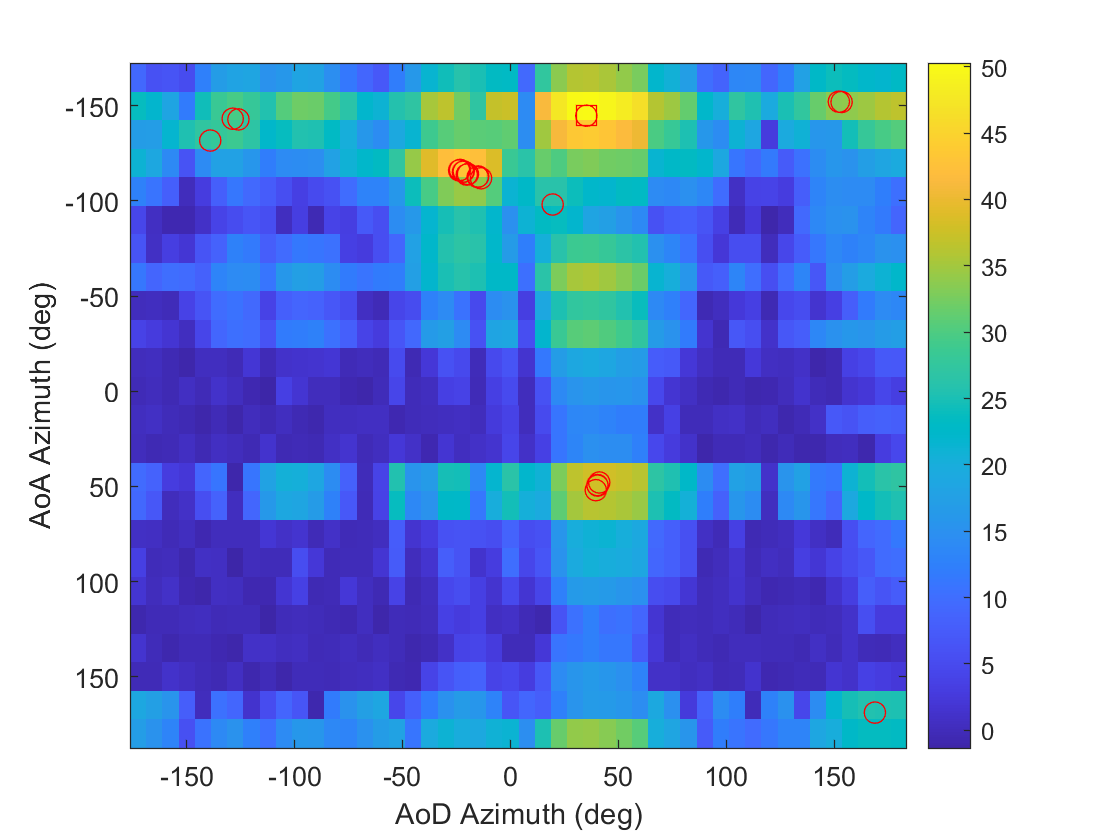

% Find the maximum over delay
[hrxMax,dlyMax] = max(abs(hrx).^2, [], 1);
hrxMax = squeeze(hrxMax);
dlyMax = squeeze(dlyMax);

% Compute SNR
hrxMean = mean(abs(hrx).^2,'all');
snrMax = pow2db(hrxMax / hrxMean);

% Plot the results
azRx = dirSim.rx.azCw;
azTx = dirSim.tx.azCw;
clf;
imagesc(azTx, azRx, snrMax);  
colorbar();
hold on;

% Find number of paths 20 dB below maximum
np = sum(dirSim.pl < dirSim.pl(1) + 30);
if np > 0
    plot(dirSim.aodAz(1), dirSim.aoaAz(1), 'rs', 'MarkerSize', 10);
end
if np > 1
    plot(dirSim.aodAz(1:np), dirSim.aoaAz(1:np), 'ro', 'MarkerSize', 8);
end
hold off;
xlabel('AoD Azimuth (deg)');
ylabel('AoA Azimuth (deg)');

We can now find the optimal codeword and array for the TX and RX.

[snrBest, im] = max(snrMax, [], 'all', 'linear');
ncwRx = size(snrMax, 1);
irx = mod(im-1,ncwRx)+1;
itx = floor((im-1)/ncwRx)+1;

% Get array indices
arrIndTx = multiArrgNB.cwArrInd(itx);
arrIndRx = multiArrUE.cwArrInd(irx);

% Print results
fprintf(1, 'Best CW indices:  TX %5d Rx %5d\n', itx, irx);

Best CW indices:  TX    29 Rx     2


fprintf(1, 'Approx angle:     TX %5.0f Rx %5.0f\n', azTx(itx), azRx(irx));

Approx angle:     TX    38 Rx  -150


fprintf(1, 'Best array:       TX %5d Rx %5d\n', arrIndTx, arrIndRx);

Best array:       TX     1 Rx     3


## Extracting the Angular Parameters

The beam search provides a coarse estimate of the AoD and AoA.  However, for localization and other tasks, we need more exact angular estimates.  There is a huge literature on estimating angular directions.  For this demo, we can use a simple  SVD-type algorithm.  This is similar to the classic MUSIC algorithm.  Note that this procedure can be only be done at the RX since it requires coherent measurements across the antennas.  Also, we will assume we have a fully digital array at the RX.  

The method is implemented in the following function.

pathEst = dirSim.estimatePaths(h, hrx);

We can plot the results.

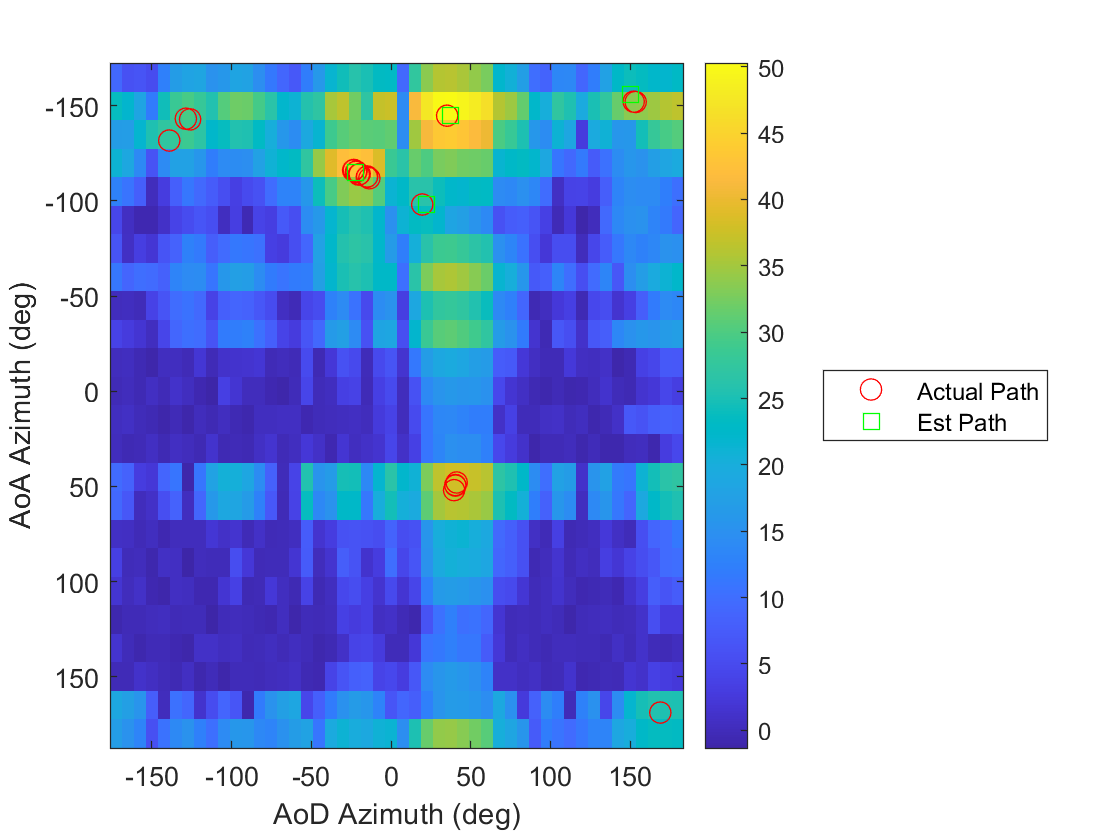

% Plot the results
azRx = dirSim.rx.azCw;
azTx = dirSim.tx.azCw;
clf;
imagesc(azTx, azRx, snrMax);  
colorbar();
hold on;

% Find number of paths 20 dB below maximum
np = sum(dirSim.pl < dirSim.pl(1) + 30);
if np > 0
    plot(dirSim.aodAz(1:np), dirSim.aoaAz(1:np), 'ro', 'MarkerSize', 8, ...
        'DisplayName','Actual Path');
end

% Plot the number of estimated paths with SNR over 25 dB
% I need to calibrate the SNR
I = find(pathEst.snr > 25);
if isempty(I)
    fprintf(1, 'No paths detected');
else
    plot(pathEst.aodAz(I), pathEst.aoaAz(I), 'gs', ...
        'MarkerSize', 8, 'DisplayName','Est Path');
end
hold off;

xlabel('AoD Azimuth (deg)');
ylabel('AoA Azimuth (deg)');
legend('Location', 'eastoutside');